# Gmsh mesh: incident, total and scattered fields

The FEM solver does not depend on how the mesh is made. Any mesher can be used as long as it provides

- `verts`: $N_v \times 2$ node coordinates $[x\ y]$ in metres,

- `cells`: $N_c \times 3$ triangle connectivity (row indices of `verts`),

plus one complex permittivity per triangle and the node index of each antenna. This example meshes the scenario of `Circular``_d``omain_target` in **Gmsh** with a Python script and runs three simulations on **two meshes**:

- `incident`: data mesh, the target region is filled with the DOI medium,

- `total`: data mesh, with the target,

- `operator`: operator mesh, no target. It gives the incident field used to build the imaging operator.

The scattered field is $E_{sc} = E_{tot} - E_{inc}$, computed on the data mesh. The operator uses a different mesh to avoid the *inverse crime*.

## Setup

clc; close all; clear;
here = fileparts(mfilename('fullpath'));                       % folder of this example
if ~isfolder(fullfile(here, '..', '..', 'Forward_solvers'))      % Live Editor: use the open file
    try, here = fileparts(matlab.desktop.editor.getActiveFilename); catch, here = pwd; end
end
addpath(fullfile(here, '..', '..'));
setup_osmi;
resultsDir = fullfile(here, 'results');

## 1. Generate the meshes (optional)

`generate``_m``eshes.py` builds both meshes with the Gmsh Python interface. Every region is a **physical group** (1 background, 2 DOI, 3 target, 4 antenna discs, 5 antenna centres) with its own element size: $\lambda/12$ in the data mesh, $\lambda/10$ in the operator mesh, $\lambda/15$ at the antennas. The meshes are already in `data/`; set `regenerate = true` to rebuild them (requires Python and `pip install gmsh`).

regenerate = false;
if regenerate
    status = system(sprintf('python "%s"', fullfile(here, 'generate_meshes.py')));
    assert(status == 0, 'Mesh generation failed: are Python and gmsh installed?');
end

## 2. Read the meshes

`readGmshMesh` returns the arrays expected by the FEM solver and the physical-group tag of every triangle.

meshData = readGmshMesh(fullfile(here, 'data', 'circular_domain_target.msh'));
meshOper = readGmshMesh(fullfile(here, 'data', 'circular_domain_operator.msh'));
fprintf('data mesh     : verts %d x %d, cells %d x %d\n', size(meshData.verts), size(meshData.cells));

data mesh     : verts 9752 x 2, cells 19142 x 3


fprintf('operator mesh : verts %d x %d, cells %d x %d\n', size(meshOper.verts), size(meshOper.cells));

operator mesh : verts 6898 x 2, cells 13494 x 3


## Regions of the two meshes

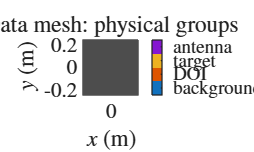

figure;
patch('Faces', meshData.cells, 'Vertices', meshData.verts, 'FaceVertexCData', meshData.region, ...
      'FaceColor', 'flat', 'EdgeColor', [0.3 0.3 0.3], 'LineWidth', 0.1);
axis equal tight; colormap(gca, lines(4)); clim([0.5 4.5]);
colorbar('Ticks', 1:4, 'TickLabels', {'background', 'DOI', 'target', 'antenna'});
xlabel('$x$ (m)'); ylabel('$y$ (m)'); title('Data mesh: physical groups');

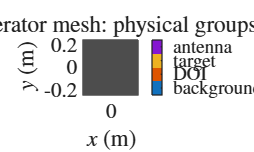


figure;
patch('Faces', meshOper.cells, 'Vertices', meshOper.verts, 'FaceVertexCData', meshOper.region, ...
      'FaceColor', 'flat', 'EdgeColor', [0.3 0.3 0.3], 'LineWidth', 0.1);
axis equal tight; colormap(gca, lines(4)); clim([0.5 4.5]);
colorbar('Ticks', 1:4, 'TickLabels', {'background', 'DOI', 'target', 'antenna'});
xlabel('$x$ (m)'); ylabel('$y$ (m)'); title('Operator mesh: physical groups');

## 3. Materials

Same materials as `Circular``_d``omain_target`:


$$\varepsilon_c = \varepsilon' - j\,\frac{\sigma}{\omega\,\varepsilon_0}$$


sim.f = 1e9;
eps0  = 8.854187817e-12;
omega = 2*pi*sim.f;

materials.background = struct('epsr', 20, 'sigma', 0.02);
materials.doi        = struct('epsr', 20, 'sigma', 0.02);
materials.target     = struct('epsr', 60, 'sigma', 0.5);

materials.background.epsc = materials.background.epsr - 1j*materials.background.sigma/(omega*eps0);
materials.doi.epsc        = materials.doi.epsr        - 1j*materials.doi.sigma/(omega*eps0);
materials.target.epsc     = materials.target.epsr     - 1j*materials.target.sigma/(omega*eps0);

## 4. Permittivity of every triangle

One value per triangle, assigned by physical group. The antenna discs have the background medium. The incident and total scenarios differ only in the triangles of the target (group 3).

permInc = zeros(size(meshData.cells, 1), 1);               % data mesh, no target
permInc(meshData.region == 1 | meshData.region == 4) = materials.background.epsc;
permInc(meshData.region == 2 | meshData.region == 3) = materials.doi.epsc;

permTot = permInc;                                         % data mesh, with target
permTot(meshData.region == 3) = materials.target.epsc;

permOper = zeros(size(meshOper.cells, 1), 1);              % operator mesh, no target
permOper(meshOper.region == 1 | meshOper.region == 4) = materials.background.epsc;
permOper(meshOper.region == 2) = materials.doi.epsc;

cellsDOIData = find(meshData.region == 2 | meshData.region == 3);
cellsDOIOper = find(meshOper.region == 2);

## 5. Antennas

The antenna centres are mesh nodes (group 5). They are sorted by angle so that antenna $n$ is the same in both meshes and in the MATLAB examples.

nodes = [meshData.points([meshData.points.tag] == 5).node]';
angles = mod(atan2(meshData.verts(nodes, 2), meshData.verts(nodes, 1)) + 1e-9, 2*pi);
[~, order] = sort(angles);
probesData = nodes(order);

nodes = [meshOper.points([meshOper.points.tag] == 5).node]';
angles = mod(atan2(meshOper.verts(nodes, 2), meshOper.verts(nodes, 1)) + 1e-9, 2*pi);
[~, order] = sort(angles);
probesOper = nodes(order);

## 6. Run the FEM

One solve per transmitter and simulation. The PML occupies the outer 25 % of the square, the default of `fem2d`.

current = 1e-3;                                            % A
incident = solve_fields(meshData.verts, meshData.cells, permInc, sim.f, probesData, ...
                        materials.background.epsc, current, cellsDOIData, "incident");
total    = solve_fields(meshData.verts, meshData.cells, permTot, sim.f, probesData, ...
                        materials.background.epsc, current, cellsDOIData, "total");
operator = solve_fields(meshOper.verts, meshOper.cells, permOper, sim.f, probesOper, ...
                        materials.background.epsc, current, cellsDOIOper, "operator");

## 7. Plot information and save

Outlines of the DOI and target, and region inside the PML.

s = 0.75 * max(abs(meshData.verts(:)));
domain = struct('pmlStart', s, 'plotLimits', s*[-1 1 -1 1]);
geom   = struct('doiRadius', 0.10, 'targetCenter', [0.03 0.03], 'targetRadius', 0.01);

incident.geom = geom;  incident.domain = domain;  incident.includeTarget = false;
total.geom    = geom;  total.domain    = domain;  total.includeTarget    = true;
operator.geom = geom;  operator.domain = domain;  operator.includeTarget = false;

save_fields(incident, "incident", resultsDir);

Saved "incident"  ->  C:\Users\ibeb\OneDrive - Ciências ULisboa\Doutoramento\Coisas uteis\School_Turim\Matlab\Examples\Gmsh_circular_domain_target\results\incident.mat


save_fields(total,    "total",    resultsDir);

Saved "total"  ->  C:\Users\ibeb\OneDrive - Ciências ULisboa\Doutoramento\Coisas uteis\School_Turim\Matlab\Examples\Gmsh_circular_domain_target\results\total.mat


save_fields(operator, "operator", resultsDir);

Saved "operator"  ->  C:\Users\ibeb\OneDrive - Ciências ULisboa\Doutoramento\Coisas uteis\School_Turim\Matlab\Examples\Gmsh_circular_domain_target\results\operator.mat


## Meshes

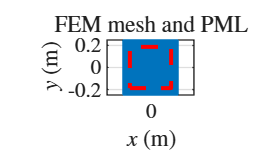

plotMesh(total);

plotMesh(operator);

## Permittivity and contrast


$$\Delta\varepsilon_r = \varepsilon_{r,\,\mathrm{total}} - \varepsilon_{r,\,\mathrm{incident}}$$


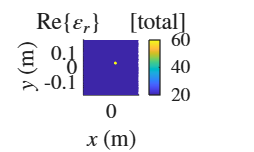

plotPermittivity(total, 'real');

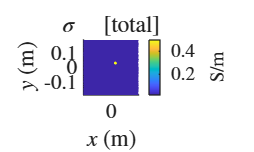

plotPermittivity(total, 'sigma');

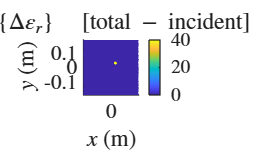

plotPermittivity(total, 'real', 'Reference', incident);

## Incident, total and scattered fields

Choose the transmitter `tx`. The scattered field is the difference of the two simulations on the data mesh (`'Reference', incident`).

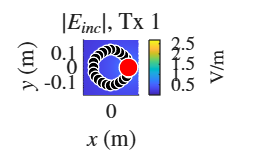

tx = 1;

plotField(incident, tx, 'abs', 'Title', "$|E_{inc}|$, Tx " + tx);

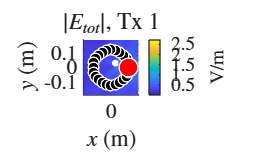

plotField(total,    tx, 'abs', 'Title', "$|E_{tot}|$, Tx " + tx);

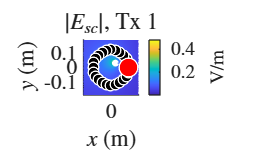

plotField(total,    tx, 'abs',   'Reference', incident, 'Title', "$|E_{sc}|$, Tx " + tx);

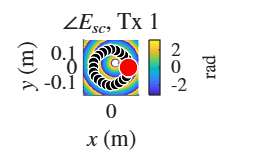

plotField(total,    tx, 'phase', 'Reference', incident, 'Title', "$\angle E_{sc}$, Tx " + tx);

## Incident field on the operator mesh

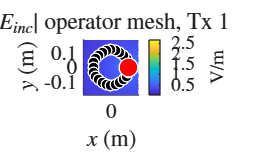

plotField(operator, tx, 'abs', 'Title', "$|E_{inc}|$ operator mesh, Tx " + tx);

## Scattered field at the antennas

The data used for imaging: $E_{sc}(m,n)$, receiver $m$, transmitter $n$.

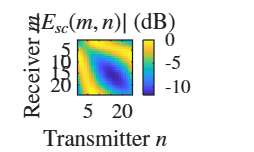

E_sc = total.Eprobes - incident.Eprobes;
figure;
imagesc(20*log10(abs(E_sc)/max(abs(E_sc(:)))));
axis image; colorbar;
xlabel('Transmitter $n$'); ylabel('Receiver $m$');
title('$|E_{sc}(m,n)|$ (dB)');

## Comparison with the MATLAB mesh

If `Circular``_d``omain_target` has been run, compare the total field at the antennas computed on the Gmsh and MATLAB meshes.

other = fullfile(here, '..', 'Circular_domain_target', 'results', 'target.mat');
if isfile(other)
    matlabTarget = load_fields(other);
    off = ~eye(numel(probesData));
    d   = norm(total.Eprobes(off) - matlabTarget.Eprobes(off)) / norm(matlabTarget.Eprobes(off));
    fprintf('Antenna data, Gmsh vs MATLAB mesh: relative difference %.3f\n', d);
end

Antenna data, Gmsh vs MATLAB mesh: relative difference 0.032


## Interactive viewer

Field: `total`, `incident` or their difference (scattered field).

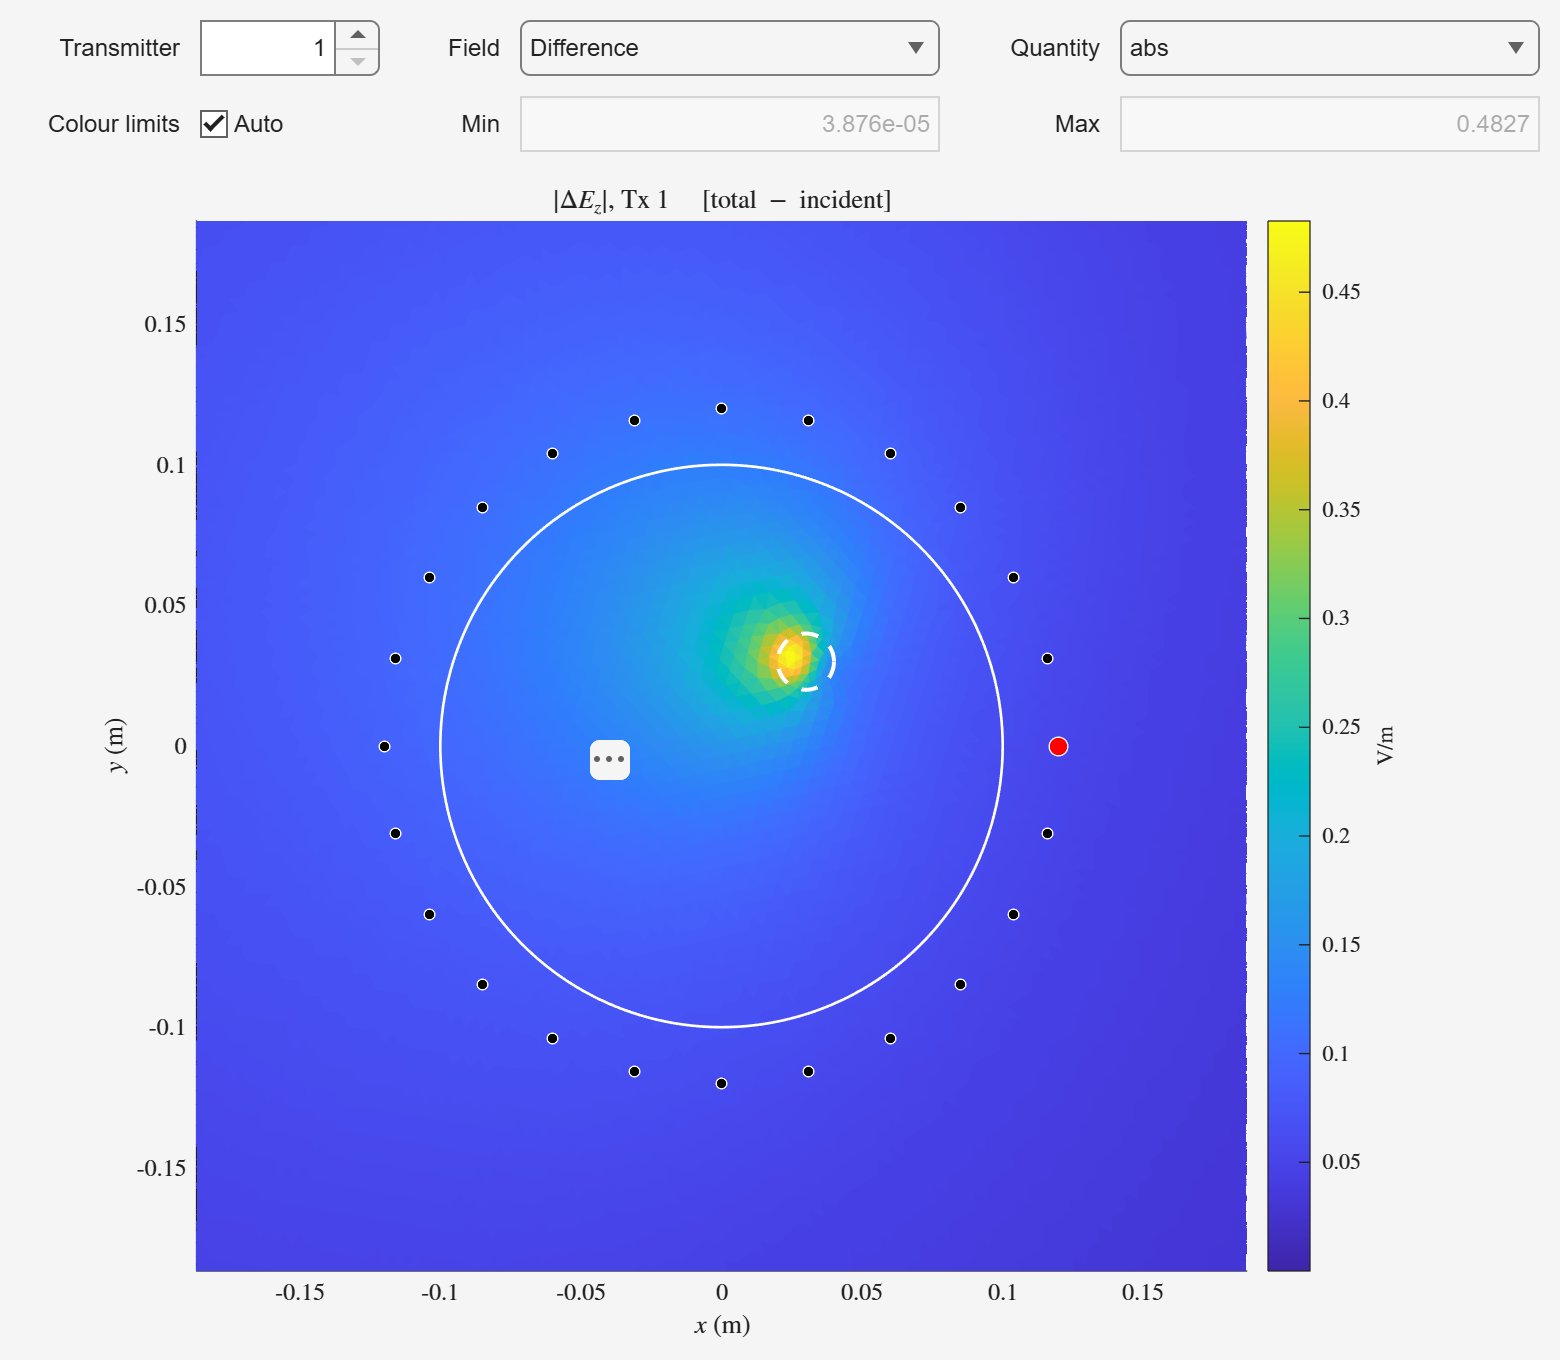

fieldViewer(total, incident);